# Compare two backgrounds

clear
clc

file1 = 'StatBackground_20240311_HSSpeed=2_VSSpeed=1';
file2 = 'StatBackground_20240327_HSSpeed=2_VSSpeed=1';

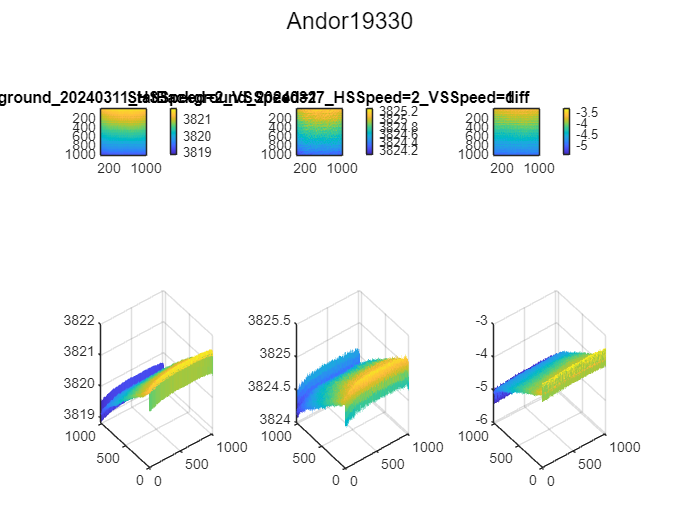

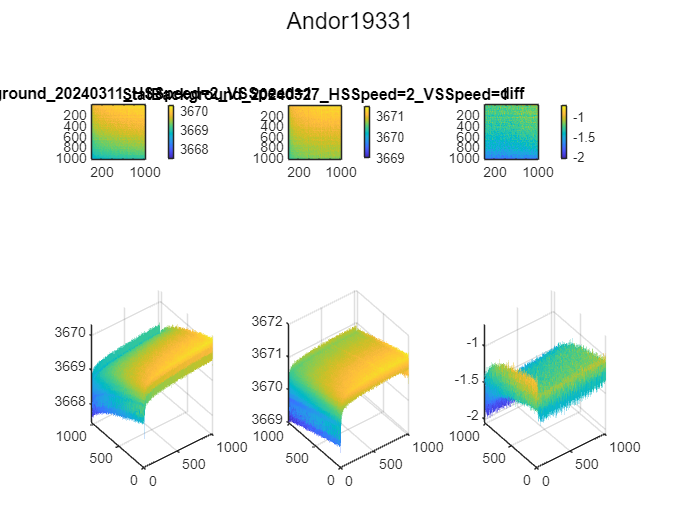

stat1 = load(fullfile('calibration',file1));
stat2 = load(fullfile('calibration',file2));

cameras = {'Andor19330','Andor19331'};
close all

for i = 1:length(cameras)
    camera = cameras{i};

    mean1 = stat1.(camera).SmoothMean;
    mean2 = stat2.(camera).SmoothMean;

    figure
    sgtitle(camera)

    subplot(2,3,1)
    imagesc(mean1)
    daspect([1 1 1])
    colorbar
    title(file1,'Interpreter','none')

    subplot(2,3,2)
    imagesc(mean2)
    daspect([1 1 1])
    colorbar
    title(file2,'Interpreter','none')

    subplot(2,3,3)
    imagesc(mean1-mean2)
    daspect([1 1 1])
    colorbar
    title('diff')

    subplot(2,3,4)
    surf(mean1,'EdgeColor','none')

    subplot(2,3,5)
    surf(mean2,'EdgeColor','none')

    subplot(2,3,6)
    surf(mean1-mean2,'EdgeColor','none')
end